clc; close all; clear all;

## Problem 3. 

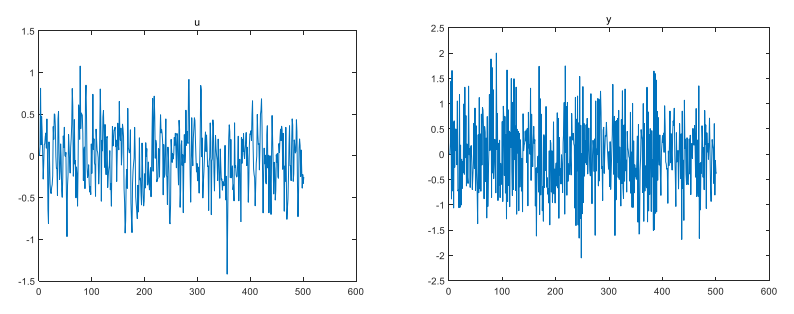

위 그림과 같이 시계열 데이터를 표현하는 운동모델이 ARX구조를 따른다고 가정할 때 아래의 문제를 푸시오.

### Problem 3-1

모델의 차수에 따른 Regressor matrix와 output vector를 정의해라

Output model $A(q^{-1})$의 차수는 $m$이고, input model $B(q^{-1})$의 차수는 $n$이다.

***Sol)***

ARX model : $A\left(q^{-1} \right)y\left(k\right)=B\left(q^{-1} \right)u\left(k\right)+e\left(k\right)$


$$y(k) = -a_1y(k-1) -a_2y(k-2) - \cdots -a_my(k-m) + b_1u(k-1) + b_2u(k-2) + \cdots + b_nu(k-n)+ e(k)$$



$$A(q^{-1}) = 1 + a_1q^{-1} + \cdots + a_mq^{-m}$$



$$B(q^{-1}) = b_1q^{-1} + b_2q^{-2} + \cdots + b_nq^{-n}$$


#### Regressor matrix $\Phi =\left\lbrack \begin{array}{cccccc}
y\left(k-1\right) & \cdots  & y\left(k-m\right) & u\left(k-1\right) & \cdots \; & u\left(k-n\right)\\
y\left(k\right) & \cdots \; & y\left(k-m+1\right) & u\left(k\right) & \cdots  & u\left(k-n+1\right)\\
\vdots  & \vdots  & \vdots  & \vdots  & \vdots  & \vdots \\
 &  &  &  &  & 
\end{array}\right\rbrack$

#### Parameter vector $\theta =\left\lbrack \begin{array}{c}
-a_1 \\
\vdots \\
-a_m \\
b_1 \\
\vdots \\
b_n 
\end{array}\right\rbrack$

**Output vector **$y=\left\lbrack \begin{array}{c}
y_l \\
y_{l+1} \\
\vdots \\
y_N 
\end{array}\right\rbrack$ 이때, $l$은 $\max(m, n) +1$이고, $N$은 데이터 수 이다.

따라서 $\hat{\theta} = (\Phi^T\Phi)^{-1}\Phi Y$

### Problem 3-2

모델의 order $(n=1,2,\ldots6)$에 따른 학습모델과 **MSE(Mean Square Error)**의 크기를 비교하시오. 이를 통해 가장 적합한 모델이 무엇인지 논의하시오.

***Sol)***

warning('off', 'all');
% 결과 가독성이 좋지 않아서 경고 문구 제외

Data = load("Prob3.mat");
model_order = 1:1:6;                % The order of model
MSE_matrix = zeros([length(model_order), length(model_order)]);
AIC_matrix = zeros([length(model_order), length(model_order)]);
BIC_matrix = zeros([length(model_order), length(model_order)]);

% noise = 0.1;
% Data.y = Data.y + noise.*randn(length(Data.y), 1);

for input_order = model_order
    for output_order = model_order
        [MSE, error] = mean_square_error(Data, input_order, output_order);
        MSE_matrix(input_order, output_order) = MSE;
        AIC_matrix(input_order, output_order) = akaike_info_criterion(Data, input_order, output_order, error);
        BIC_matrix(input_order, output_order) = bayesian_info_criterion(Data, input_order, output_order, error);
    end
end
[value, index] = min(MSE_matrix);
[val, idx] = min(value);
[theta, A_q, B_q] = least_square(Data, 3, 4);
[idx, index(idx)]

ans =      3     4


즉, $B(q^{-1})$는 3**차** $A(q^{-1})$는 4**차 시스템 모델**이 가장 MSE가 작은 모습을 보여준다. 

모델 선정을 위해 MSE, AIC, BIC에 대해 surface를 그려보았다.

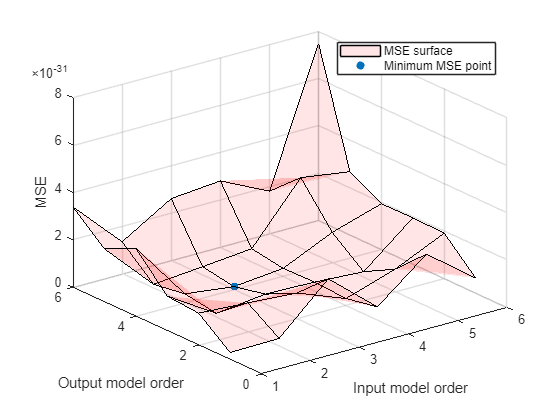

[rows, cols] = size(MSE_matrix);
[X, Y] = meshgrid(1:cols, 1:rows);
MSE = surf(X, Y, MSE_matrix,'FaceAlpha', 0.1, 'FaceColor','flat');
MSE.FaceColor = "red";
xlabel("Input model order"); ylabel("Output model order"); zlabel("MSE");
hold on
Minpoint = scatter3(idx, index(idx), val, 'filled', 'LineWidth', 3);
legend([MSE, Minpoint], {"MSE surface", "Minimum MSE point"}, "Location","northeast")
hold off

[value, index] = min(AIC_matrix);
[val, idx] = min(value);
[idx, index(idx)]

ans =      3     4


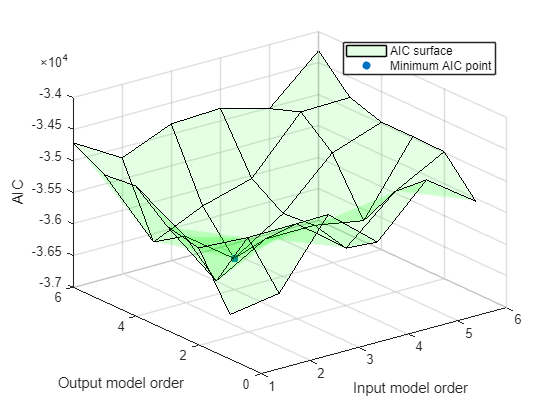

AIC = surf(X, Y, AIC_matrix, 'FaceAlpha', 0.1, 'FaceColor', 'flat');
AIC.FaceColor = "green";
hold on
Minpoint = scatter3(idx, index(idx), val, 'filled', 'LineWidth', 3);
hold off
xlabel("Input model order"); ylabel("Output model order"); zlabel("AIC");
legend([AIC, Minpoint], {"AIC surface", "Minimum AIC point"}, "Location","northeast")

[value, index] = min(BIC_matrix);
[val, idx] = min(value);
[idx, index(idx)]

ans =      3     4


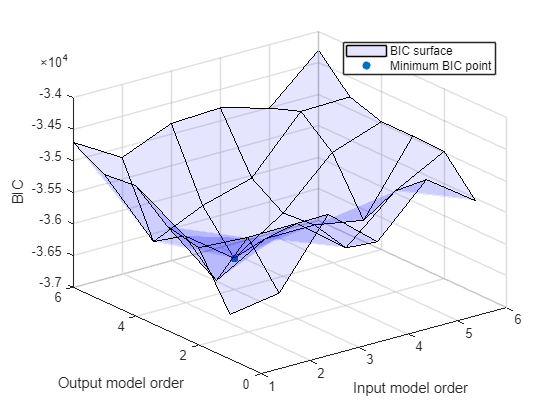

BIC = surf(X, Y, BIC_matrix, 'FaceAlpha', 0.1, 'FaceColor','flat');
BIC.FaceColor = "blue";
hold on
Minpoint = scatter3(idx, index(idx), val, 'filled', 'LineWidth', 3);
hold off
xlabel("Input model order"); ylabel("Output model order"); zlabel("BIC");
legend([BIC, Minpoint], {"BIC surface", "Minimum BIC point"}, "Location","northeast")

MSE, AIC, BIC 모두 가장 작은 값은 input model $B(q^{-1})$가 3차일때, output model $A(q^{-1})$는 4차 시스템 모델일 때 가장 작은 모습을 보여준다. 따라서 가장 적합한 모델은

[theta, A_q, B_q] = least_square(Data, 3, 4);
A_q = [1, -A_q];
B_q = [0, B_q];
sys = tf(B_q, A_q, 0.1, 'Variable', 'z^-1')

sys =
 
               2 z^-1 - 1.275 z^-2 + 0.4464 z^-3
  ------------------------------------------------------------
  1 + 0.1625 z^-1 - 0.2868 z^-2 + 0.1786 z^-3 + 1.318e-16 z^-4
 
샘플 시간: 0.1 seconds
이산시간 전달 함수입니다.
모델 속성


위와 같다고 할 수 있다.

### Problem 3-3

모델의 order 별 시스템의 pole과 zero를 복소평면에 나타내고, 시스템의 안정성과 가장 적절한 모델이 무엇인지 논의하시오.

***Sol)***

Root locus 그림들은 `Problem3_root_locus` 내에 있습니다.

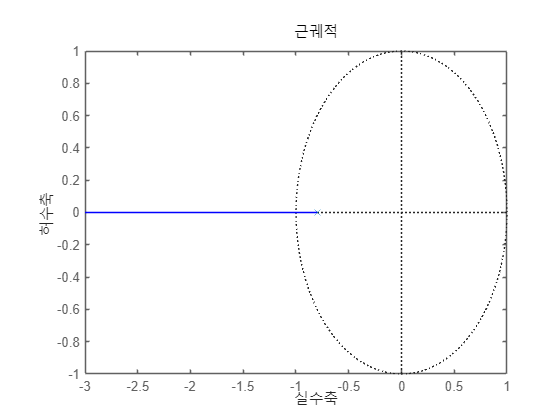

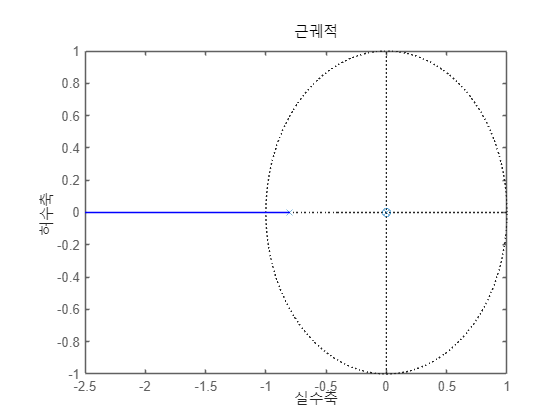

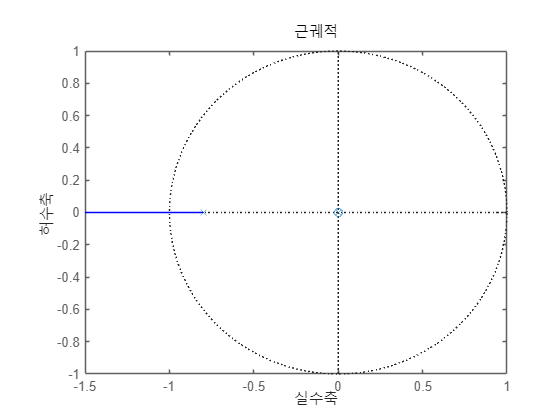

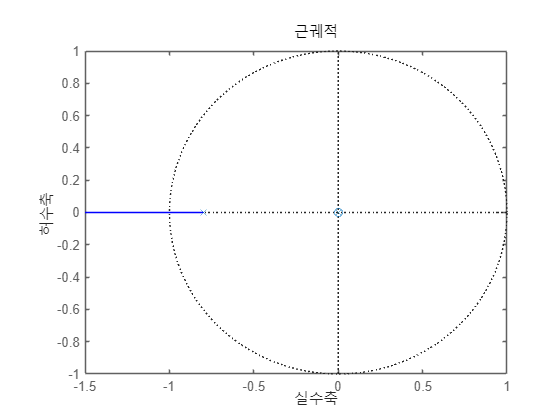

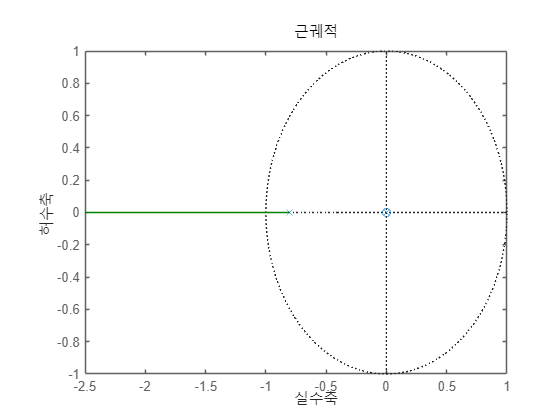

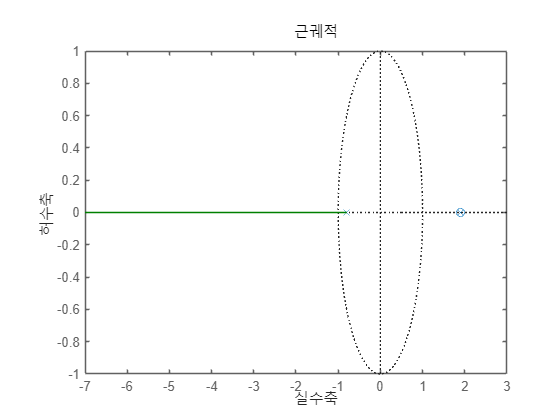

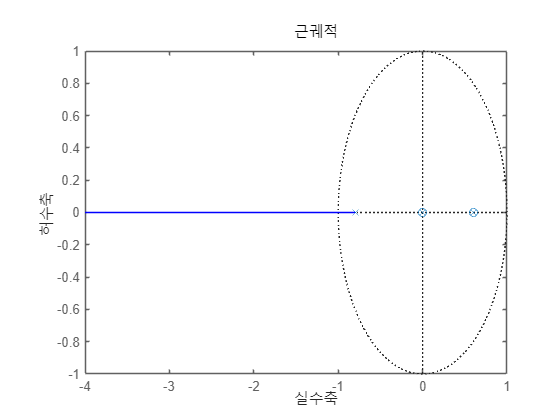

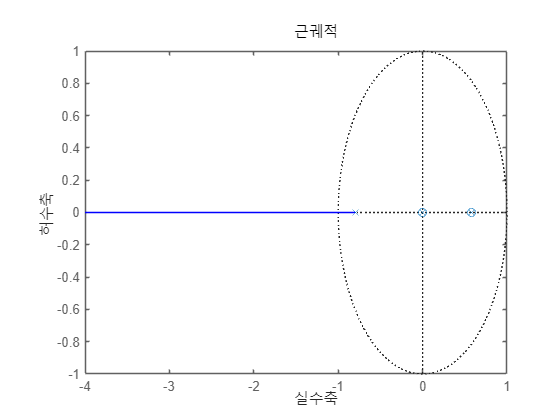

for input_order = model_order
    for output_order = model_order
        idx = idx + 1;
        figure(idx);
        discrete_sys_rlocus(Data, input_order, output_order);
        title = "rlocus_input_" + num2str(input_order) + "_output_" + num2str(output_order);
        pngname = "Problem3_root_locus/" + title + ".png";
        print(pngname, "-dpng", "-r500");
    end
end

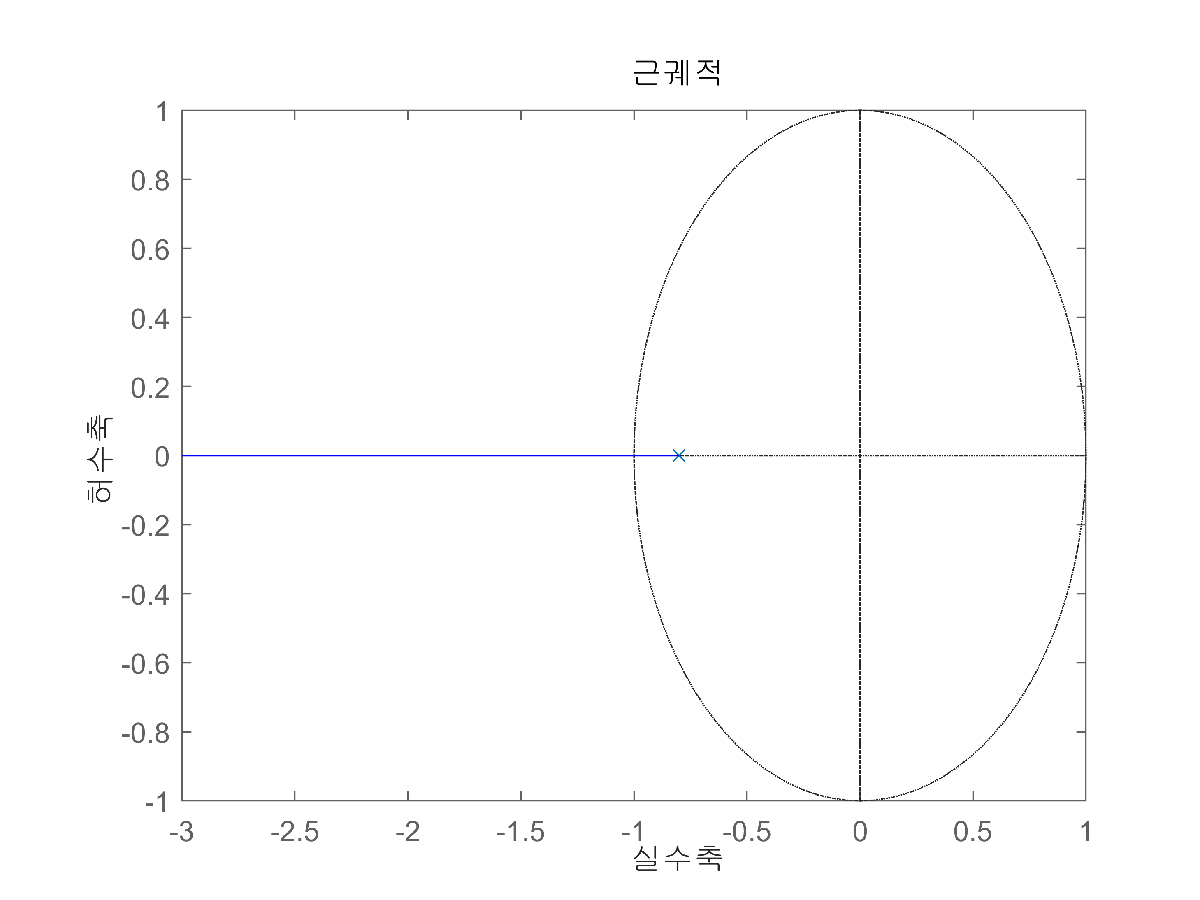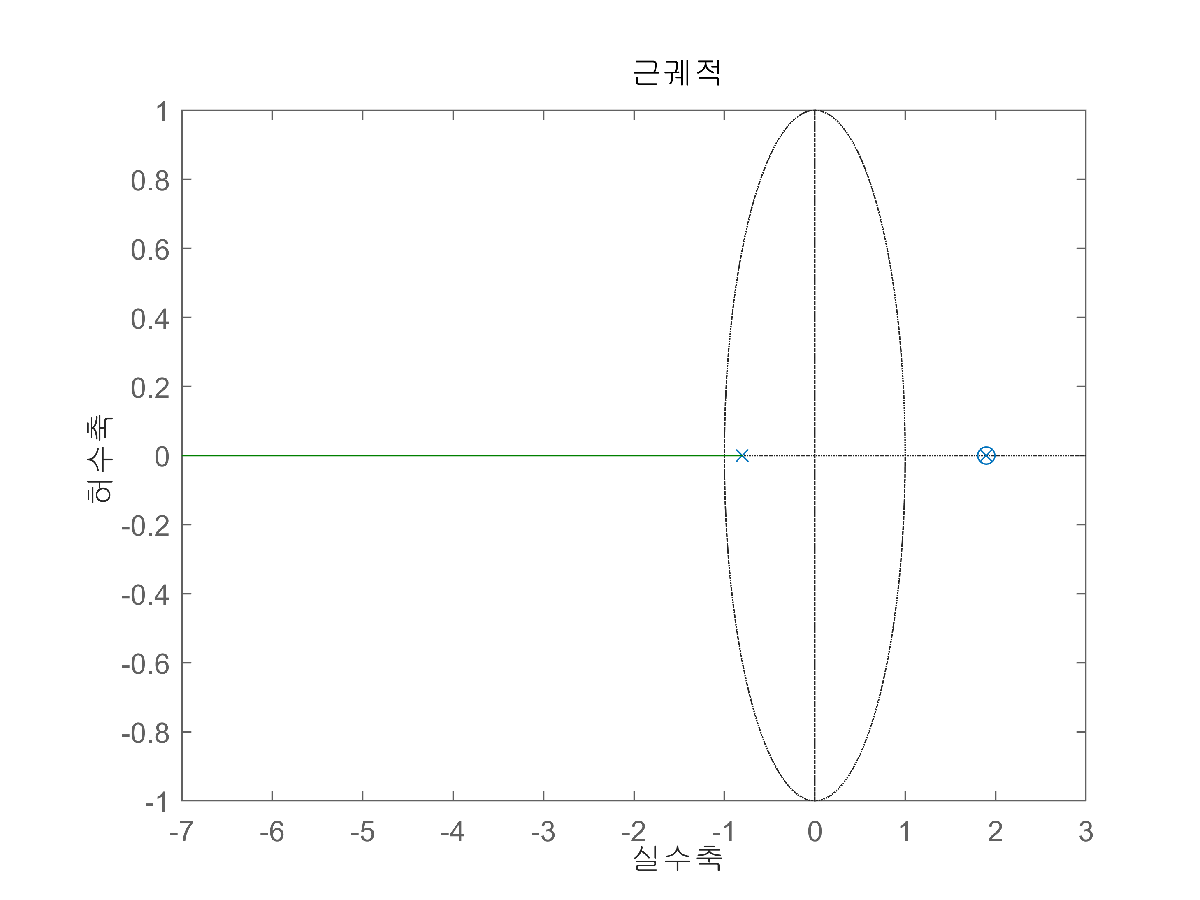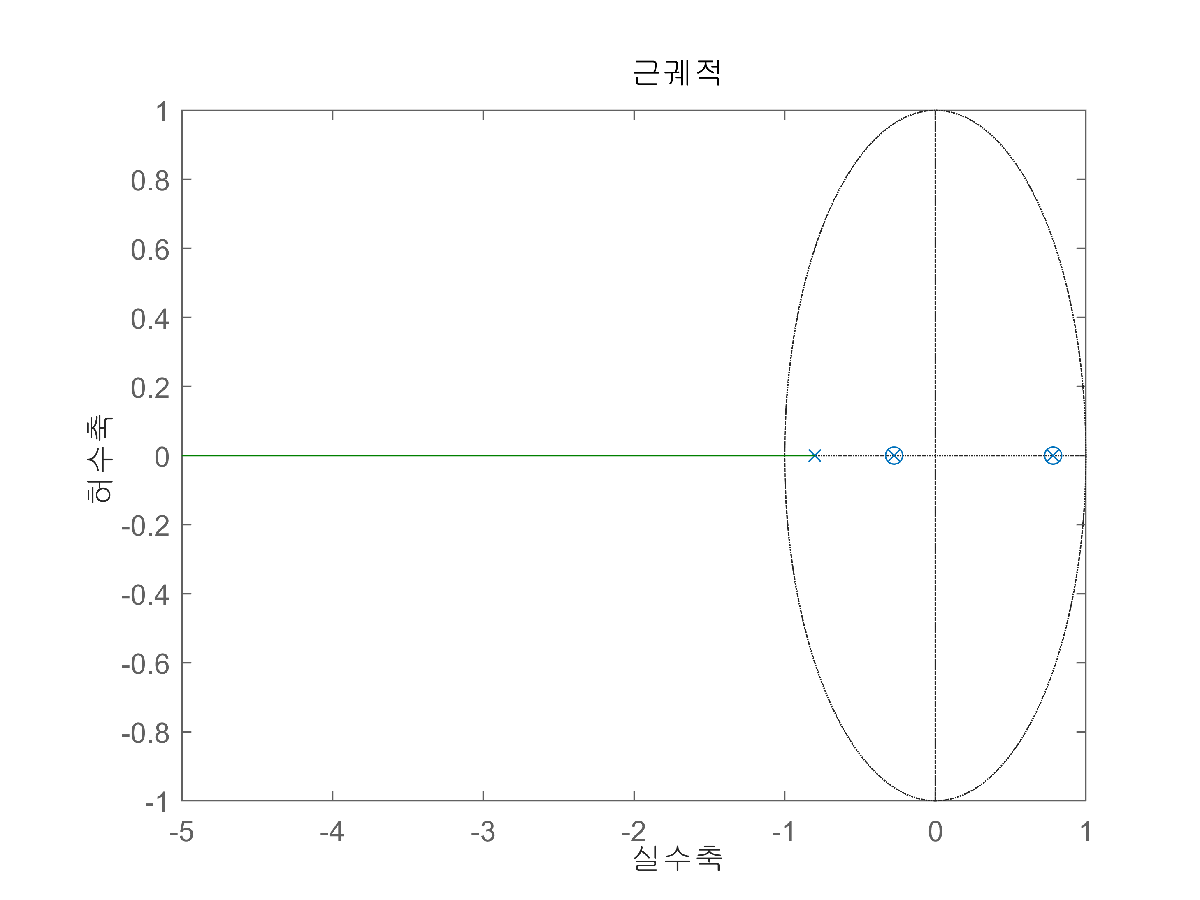

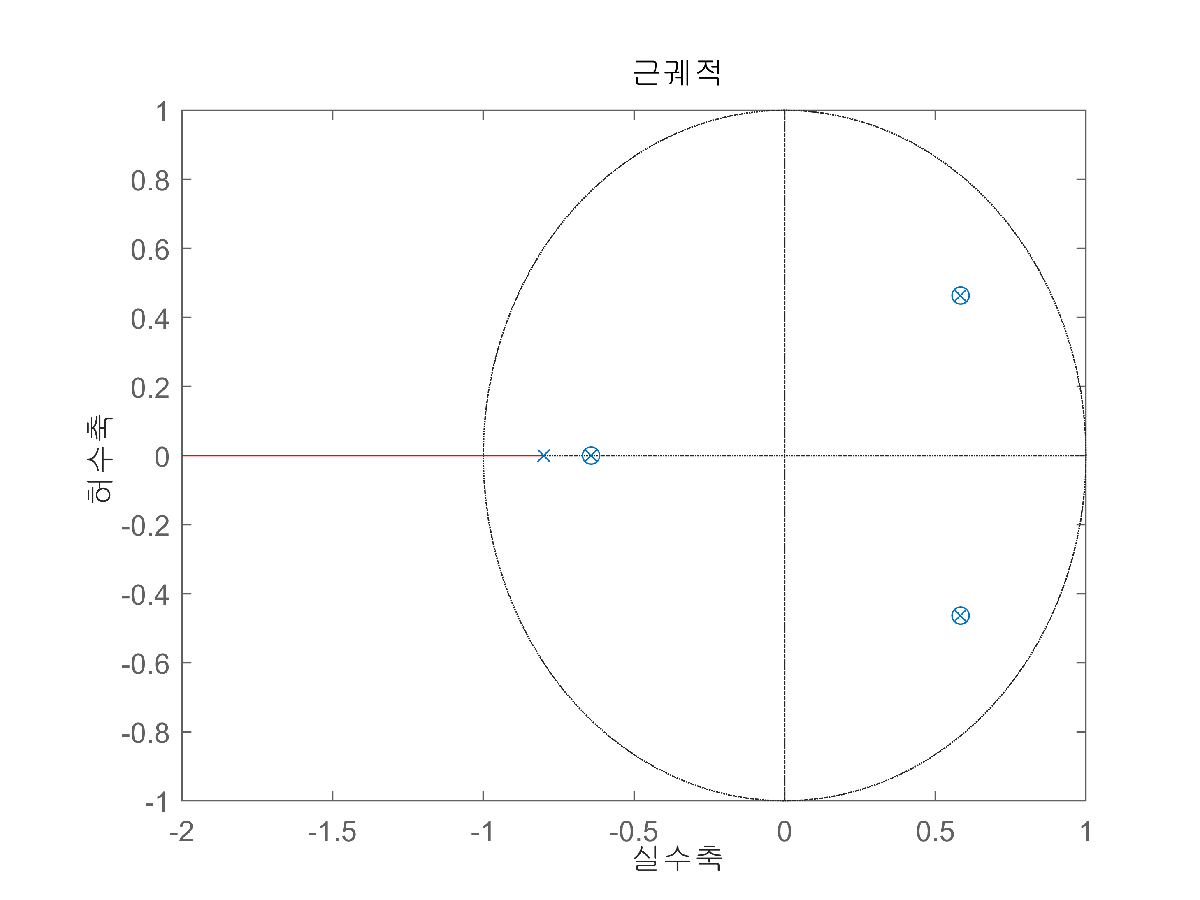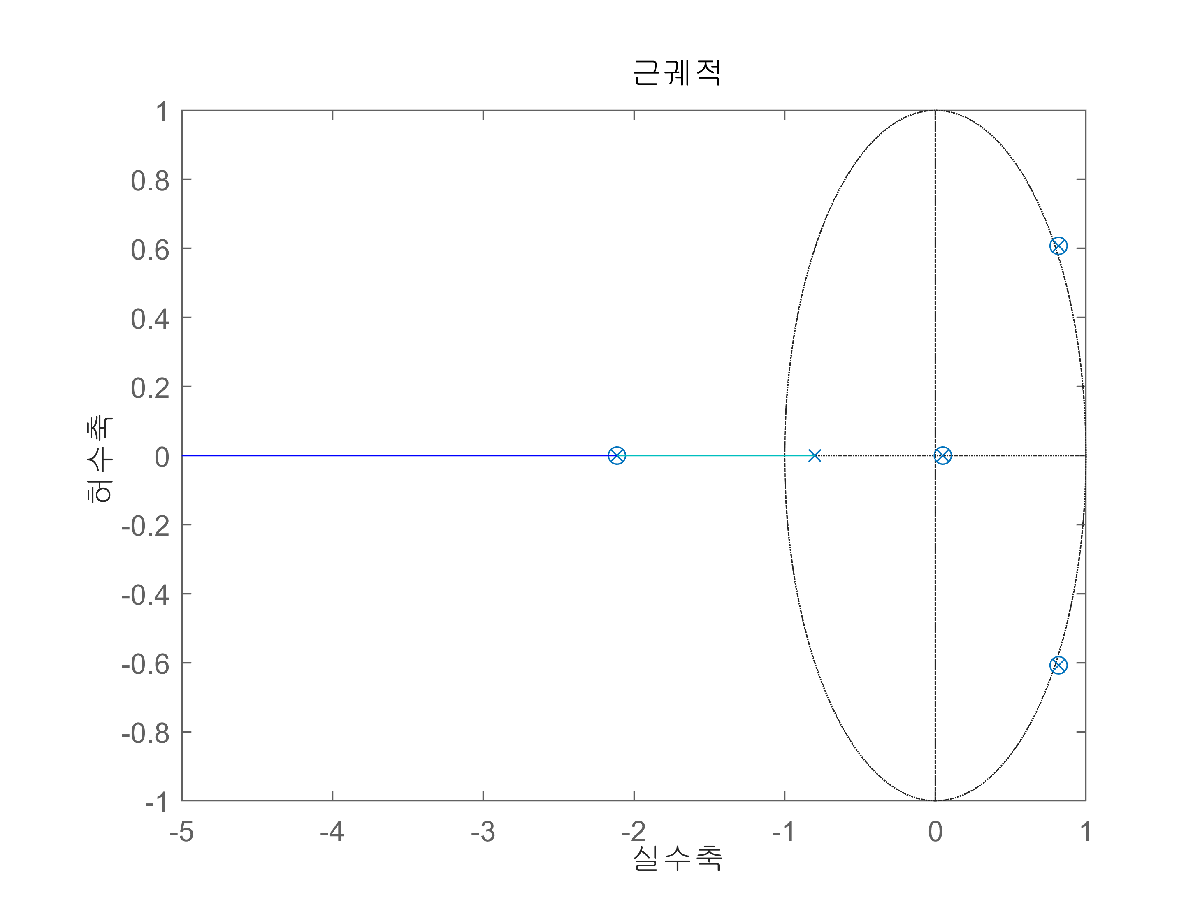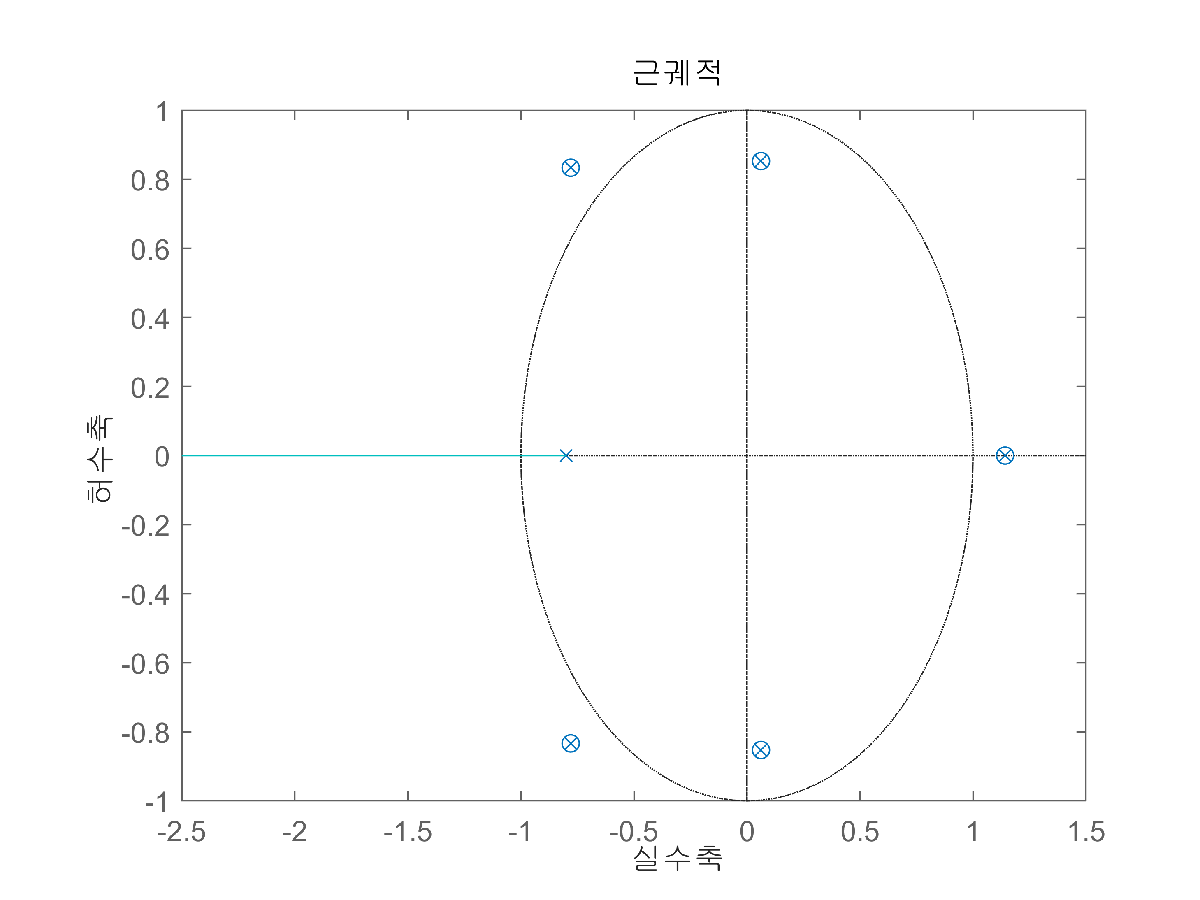

위에서부터 Input model $B(q^{-1})$, output model $A(q^{-1})$이 (1차, 1차), (2차, 2차), (3차, 3차), (4차, 4차), (5차, 5차), (6차, 6차)에 대해서 root locus들을 그려보았을 때, 3차 이상의 시스템에선 zero와 pole이 pole -0.8을 제외하곤 겹치는 모습을 띈다. 이는 불안정한 시스템의 기준인 단위원 밖에서도 마찬가지이다. 이것은 시스템의 차수가 (3차, 3차) 이상 부터는 다른 pole 들이 거의 시스템에 유의미한 영향을 주지 못한다는 것을 의미하게 된다. 즉, 앞서 MSE, AIC, BIC로 선정한 모델 또한 비교적 너무 고차 항이어서 불필요한 pole, zero가 나타나는 것으로도 해석할 수 있다.

discrete_sys_rlocus(Data, 3, 4)

`Problem3_root_locus` 폴더 내에서 heuristic search를 통해 input model이 1차일 때, output model이 2차일 때 root locus 위의 pole 중 하나가 조금이라도 zero에서 멀어진 모습을 보여준다.

discrete_sys_rlocus(Data, 1, 2)

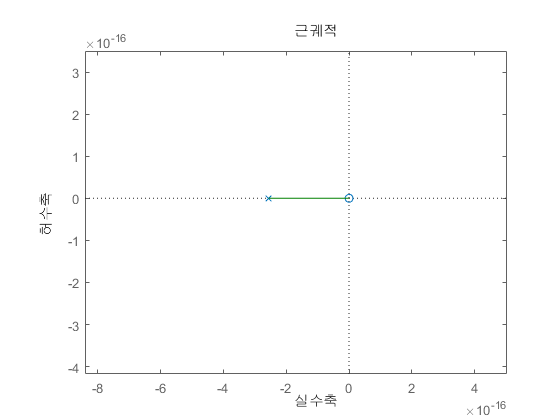

따라서 이를 바탕으로 시스템을 선정했을 때, MATLAB에서 제공하는 system identification tool box로 구한 모델과 가장 유사한 모습을 확인할 수 있었다.

***MATLAB Funciton comparison***

A_q = 2;
B_q = 1;
IOdelay = 1;
arx([Data.y, Data.u],[A_q, B_q, IOdelay],'Ts',0.1)    % arx function used

ans =
이산시간 ARX 모델: A(z)y(t) = B(z)u(t) + e(t)
  A(z) = 1 + 0.8 z^-1 - 9.622e-17 z^-2 
                                       
  B(z) = 2 z^-1                        
                                       
샘플 시간: 0.1 seconds
  
파라미터화:
   다항식 차수:   na=2   nb=1   nk=1
   자유 계수의 개수: 3
   파라미터 및 그 불확실성을 얻으려면 "polydata", "getpvec", "getcov"를 사용하십시오.

상태:                                
시간 영역 데이터에 대해 ARX을(를) 사용하여 추정되었습니다.
추정 데이터에 피팅: 100%(예측 중점)            
FPE: 2.184e-32, MSE: 2.141e-32     
 
모델 속성


[theta, A_q, B_q] = least_square(Data, 1, 2);
A_q = [1, -A_q];
B_q = [0, B_q];
tf(B_q, A_q, "Ts", 0.1, 'Variable', 'z^-1')

ans =
 
             2 z^-1
  -----------------------------
  1 + 0.8 z^-1 + 2.047e-16 z^-2
 
샘플 시간: 0.1 seconds
이산시간 전달 함수입니다.
모델 속성


## Regressor matrix

function Phi = regressor_matrix(data, input_order, output_order)
    % Data와 input order, output order의 차수를 받아 regressor matrix Phi를 도출
    % data에는 input u, output y가 무조건 존재해야함
    if ~isfield(data, 'y') || ~isfield(data, 'u')
        error("Input data must contain y and u");
    end
    % Data field 확인 절차
    if length(data.y) < output_order || length(data.u) < input_order
        error("Insufficient data points in y, u");
    end
    % Data 길이 확인
    order = max(input_order, output_order);
    Phi = zeros([length(data.y)-order, input_order+output_order]);
    idx = 0;
    for i = order+1 : length(data.u)
        idx = idx + 1;
        Phi(idx, :) = [flip(data.y(i-output_order:i-1)'), flip(data.u(i-input_order:i-1)')];
    end
end

## Model derivation

function [theta, A_q, B_q] = least_square(data, input_order, output_order)
    Phi = regressor_matrix(data, input_order, output_order);
    order = max(input_order, output_order);
    Output = data.y(order+1:end);
    theta = (Phi'*Phi)\Phi'*Output;
    A_q = theta(1:output_order)';
    B_q = theta(output_order+1:input_order+output_order)';
end

## MSE(Mean Square Error)

function [mse, error] = mean_square_error(data, input_order, output_order)
    Phi = regressor_matrix(data, input_order, output_order);
    [theta, A_q, B_q] = least_square(data, input_order, output_order);
    output_matrix = Phi(:, 1:output_order);
    input_matrix = Phi(:, (output_order+1):(input_order+output_order));
    order = max(input_order, output_order);
    output_vector = data.y(order+1:end);
    error = output_vector - Phi*theta;
    mse = (error'*error)/length(error);
end

## AIC

function aic = akaike_info_criterion(data, input_order, output_order, error)
    % N : the number of error
    % d : the number of parameter
    Phi = regressor_matrix(data, input_order, output_order);
    % N = numel(Phi);
    N = length(error);
    d = output_order + input_order + 1;
    aic = N * log((error'*error)/N) + 2*d;
end

## BIC

function bic = bayesian_info_criterion(data, input_order, output_order, error)
    % N : the number of error
    % d : the number of parameter
    Phi = regressor_matrix(data, input_order, output_order);
    % N = numel(Phi);
    N = length(error);
    d = output_order + input_order + 1;
    bic = N * log((error'*error)/N) + d*log10(N);
end

## Root locus

function discrete_sys_rlocus(data, input_order, output_order)
    [theta, A_q, B_q] = least_square(data, input_order, output_order);
    A_q = [1, -A_q];
    B_q = [0, B_q];
    sys = tf(B_q, A_q, 0.1, 'Variable', 'q^-1');
    rlocus(sys);
end